l_1 = -10 -10j

l_1 = -10.0000 -10.0000i

l_2 = -10 +10j

l_2 = -10.0000 +10.0000i

l_3 = -1000

l_3 = -1000


W = tf(abs(l_1 * l_2 * l_3), conv(conv([1, -l_1], [1, -l_2]), [1, -l_3]));
[y, t] = step(W)

y =          0
    0.0014
    0.0065
    0.0151
    0.0270
    0.0418
    0.0592
    0.0789
    0.1005
    0.1239


t =          0
    0.0046
    0.0092
    0.0138
    0.0184
    0.0230
    0.0276
    0.0322
    0.0368
    0.0414


S = stepinfo(W, ST=0.05)

S = struct with fields:
         RiseTime: 0.1519
    TransientTime: 0.2082
     SettlingTime: 0.2082
      SettlingMin: 0.9005
      SettlingMax: 1.0432
        Overshoot: 4.3192
       Undershoot: 0
             Peak: 1.0432
         PeakTime: 0.3132


oversh_ = S.Overshoot

oversh_ = 4.3192

set_time = S.SettlingTime

set_time = 0.2082

set_val = y(end)

set_val = 0.9981

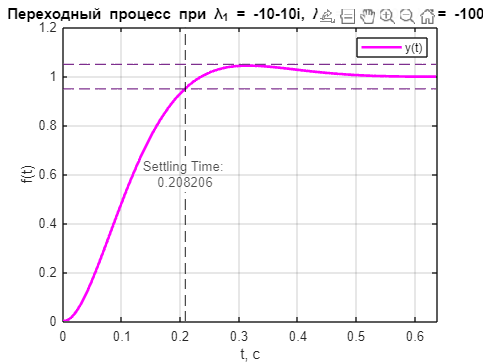


plot(t, y, 'm-', 'LineWidth', 2)
hold on
xline(set_time, 'k--', {'Settling Time: ', set_time}, LabelOrientation ='horizontal', LineWidth=1, ...
    LabelHorizontalAlignment='center', LabelVerticalAlignment='middle');

plot(t, ones(size(t)) * set_val * 0.95, '--', 'LineWidth', 1, Color=[0.4940 0.1840 0.5560]); 
plot(t, ones(size(t)) * set_val * 1.05, '--', 'LineWidth', 1, Color=[0.4940 0.1840 0.5560]); 
xlim([0 0.638])
grid()
title('Переходный процесс при λ_1 = -10-10i, λ_2 = -10+10i, λ_3 = -1000')
legend('y(t)')
ylabel('f(t)')
xlabel('t, с')
hold off